% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clear all; close all;


## Creation de la carte

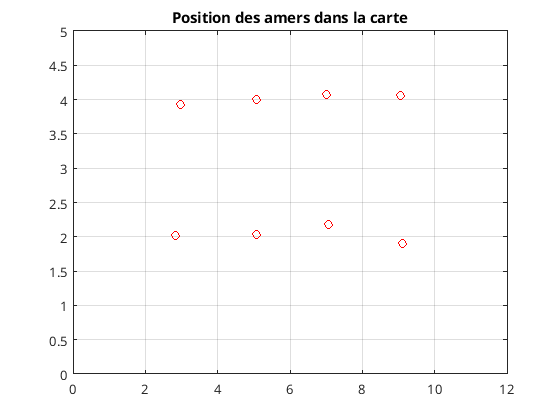

%Distances entre les amers
distXamer = 2;
disYamer = -2;

%Position des amers, vecteur de position des amers :
%    - elements impairs : position en X de l'amer 2*i-1
%    - elements pairs : position en Y de l'amer 2*i
amer=[3 ;4];

for i=2:4
    amer(2*i-1) = amer(2*i-3)+distXamer;
    amer(2*i) = amer(2);
end
for i=5:8
    amer(2*i-1) = amer(2*i-9);
    amer(2*i) = amer(2)+disYamer;
end
%Ajout de bruit dans la position des amers
dispAmers = 2/3*10^(-2) *ones(1,16);
amer = amer + chol(diag(dispAmers))'*randn(16,1);

%Affichage des amers
figure(1)
plot(amer(1:2:16), amer(2:2:16), 'or')
grid on 
axis([0 12 0 5])
title("Position des amers dans la carte")

## Génération de la trajectoire du robot

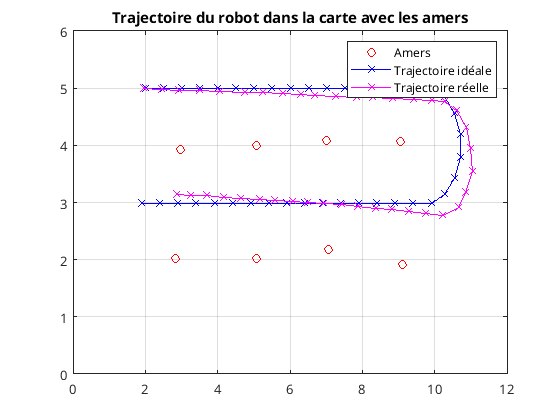

%Nombre d'instants
N1 = 15;
N2 = 8;
N3 = 17;
N = N1+N2+N3;

%Genération de la position du robot 
%Position initiale
Xr(:,1) = [2;5;0];
%Ajout du bruit
dispX0 = [1/3*10^(-2) 1/3*10^(-2) .0005/3*10];
Xrb(:,1) = Xr(:,1) + chol(diag(dispX0))'*randn(3,1);
%Vecteur de commande
for i=1:N1
    U(:,i)=[0.5;0;0];
end
for i=N1+1:N1+N2
    U(:,i)=[0.4;0;-pi/N2];
end
for i=N1+N2+1:N1+N2+N3
    U(:,i)=[0.5;0;0];
end
%Boucle de generation de la trajectoire
for i=2:N
    Xr(:,i) = dynRob(Xr(:,i-1), U(:,i-1));
    Xrb(:,i) = dynRob(Xrb(:,i-1), U(:,i-1));
    %Ajout du bruit
    dispX = [1/3*10^(-2) 1*10^(-7) .1/3*10^(-3)];
    Xrb(:,i) = Xrb(:,i) + chol(diag(dispX))'*randn(3,1);
end

%Affichage de la trajectoire du robot 
figure(2)
plot(amer(1:2:16), amer(2:2:16), 'or')
hold on
plot(Xr(1,:), Xr(2,:), 'x-b')
plot(Xrb(1,:), Xrb(2,:), 'x-m')
hold off
axis([0 12 0 6])
grid on
title("Trajectoire du robot dans la carte avec les amers")
legend('Amers', 'Trajectoire idéale', 'Trajectoire réelle')

## Generation des données de vision 

distVision = 2;
%Pas de mesures a l'etat initial 
z(:,1) = NaN * ones(2*8,1);

%Genrations de mesures pour les instants 2 a N
for k=2:N
    for j=1:8
        z(2*j-1,k) = sqrt((amer(2*j-1)-Xrb(1,k))^2+(amer(2*j)-Xrb(2,k))^2);
        z(2*j,k) = atan2((amer(2*j)-Xrb(2,k)),(amer(2*j-1)-Xrb(1,k)))-Xrb(3,k);
    end
end

%Suppression des données hors du champ de vision 
for k=2:N
    for j=1:8
        if(z(2*j-1,k)>distVision)
            z(2*j-1,k) = NaN;
            z(2*j,k) = NaN;
        end
    end
end
%Affichage du champ de vision
for k=1:N
    figure(3)
    plot(amer(1:2:16), amer(2:2:16), 'or');
    grid on
    hold on
    axis([0 15 0 15]);
    plot(Xrb(1,k), Xrb(2,k), 'xb');
    cercle(Xrb(1:2,k), distVision, 'b');
    hold off
    title('Evolution du champ de vision du robot')
    drawnow
    pause(0.25)
end

% Ajout du bruit sur les mesures 
Rv = diag([.1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2 .1^2]);
Zbruit = cell(1,N);
for i = 1:N
    Zbruit{i} = z(:,i) + chol(Rv)'*randn(16,1);
end

## Données pour le filtrage

% Creation de la structure d'etat reel 
Xreel = cell(1, N);
for i = 1:N 
    Xreel{i} = [Xrb(:,i) ; amer];
end

%Creation des structures de donnees pour le filtre 
Xpred = cell(1,N);
Xest = cell(1, N);
Ppred = cell(1,N);
Pest = cell(1,N);

%Matrice de covariance des bruits (Rv deja creee)
PX0 = diag([dispX0 dispAmers]);
Qw = diag([dispX (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2 (1e-10)^2]);

ans =     19    19


## Filtrage

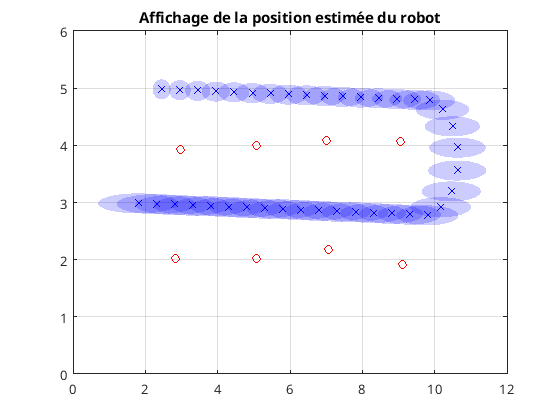

% Initialisation du filtre 
Xpred{1} = [Xrb(:, 1)];
Ppred{1} = NaN;
Xest{1} = [Xrb(:, 1)];
Pest{1} = diag([dispX0 dispAmers]);

%Matrice Fk, termes constants 
Fk = zeros(19);
Fk(1,1) = 1;
Fk(2,2) = 1;
Fk(3,3) = 1;


figure(4)
plot(amer(1:2:16), amer(2:2:16), 'or');
hold on 
title("Affichage de la position estimée du robot")
axis([0 12 0 6]);
grid on

%Boucle de simulation du filtre + affichage des données "en temps reel" avec l'etat reel des amers de du robot + elipse de bruit 
for k = 2:N
    %Prediction 
    Xpred{k} = dynRob(Xest{k-1}, U(:,k-1));
    
    %Mise a jour des termes variables de Fk
    Fk(3,1) = -U(1,k-1)*sin(Xest{k-1}(3))-U(2,k-1)*cos(Xest{k-1}(3));
    Fk(3,2) = U(1,k-1)*cos(Xest{k-1}(3))-U(2,k-1)*sin(Xest{k-1}(3));
    Ppred{k} = Fk*Pest{k-1}*Fk' + Qw;
    
    %Mise à jour
    %Idee pour la mise a jour. A chaque iteration, parcourir l'ensemble des
    %mesures de deux en deux (de 1 jusqu'a 15). Pour chaque element non
    %NaN, ajouter l'element dans un vecteur zutile + ajouter l'element
    %correspondant dans la jacobienne. 
    Xest{k} = Xpred{k};
    Pest{k} = Ppred{k};
    
    %Affichage
    plot(Xpred{k}(1),Xpred{k}(2), 'xb')
    ellipse(Xpred{k}(1:2), Ppred{k}(1:2, 1:2), 'b');
    drawnow
    pause(0.25)
end

## Estimation de la qualité du filtre 